clear
clc
close all

ModularAplysia_1282022_withSNS_initialization;
load("params_1282022.mat")
endTime = 80;

load("loaded-swallow-median-data.mat");
animal_time = (0:length(block.segments{1, 1}.analogsignals{1, 21}.signal) - 1)/block.segments{1, 1}.analogsignals{1, 21}.sampling_rate;
rows = length(block.segments{1, 1}.analogsignals) / 3 + 1;
xlim = [0, max(animal_time)];
animal_boundaries = block.segments{1, 1}.events{1, 1}.times;
animal_boundaries = animal_boundaries - block.segments{1, 1}.analogsignals{1, 1}.t_start;
xticks = (animal_boundaries(2:end) + animal_boundaries(1:end-1)) / 2;
xticklabels = ["V","I","II","III","IV","V"];

colorset = {[240, 191, 70]/255;...
    [220, 82, 82]/255;...
    [207, 132, 186]/255;...
    [101, 181, 206]/255;...
    [79, 127, 189]/255;...
    [0, 168, 107]/255;...
    [0, 0, 0]/255;};
ylimset = {[0, 20];...
    [0, 20];...
    [0, 40];...
    [0, 50];...
    [0, 10];...
    [0, 20];...
    [0, 300]};
linewidth = 1.75;
tickwidth = 1;
markersize = 5;
barcolor = [0.6, 0.6, 0.6];
barwidth = 0.75;
capsize = 3;
fillalpha = 0.6;
linealpha = 0.3;
point_num = 20;
% point_num = 621;

discrete_animal_time = linspace(0,animal_time(end),point_num);
mean_signal_set = zeros([rows - 1, length(discrete_animal_time)]);
for k = 1:rows - 1
    mean_signal = block.segments{1, 1}.analogsignals{1, 3 * k}.signal;
    peak_value_animal = max(mean_signal);
    mean_signal = mean_signal / peak_value_animal;
    mean_signal_set(k,:) = interp1(animal_time,mean_signal,discrete_animal_time);
end

% mu_s_g = 0.43;
% mu_k_g = 0.3;
% mu_s_h = 0.3;
% mu_k_h = 0.3;
mu_s_g = 0.45;
mu_k_g = 0.3;
mu_s_h = 0.3;
mu_k_h = 0.3;
max_I3ant = 1.2;
seaweed_strength = 10;

sens_chemical_lips = 1;
sens_mechanical_lips = 1;
sens_mechanical_grasper = 1;
fixation_type = 1;
%Run ModularAplysia with the original biomechanics and SNS control


simout = sim('ModularAplysia_1282022_withSNS_originalMechanics.slx', 'StopTime',string(endTime),'MinStep','0.001');

[model_index, model_time, model_boundaries] = time_normalization(simout,animal_boundaries,animal_time);
model_output = {simout.f_B38(model_index);...
    simout.A_I2(model_index);...
    simout.f_B8(model_index);...
    simout.f_B69(model_index);...
    simout.f_B69(model_index);...
    simout.f_B45(model_index);...
    simout.force(model_index);...
    simout.xgh(model_index)};

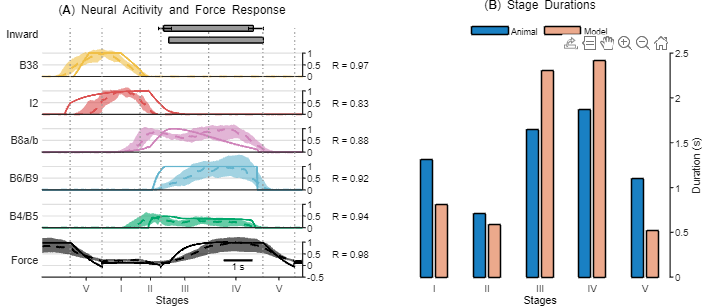

figure_width = 840 * 0.78 * 1.2;
figure_height = 400 * 0.85;
f = figure;
set(gcf,'Color','white');
set(gcf,'position',[0,0,figure_width,figure_height]);
ax = cell(rows - 1,2);
for k = 1:rows
    if k < 2
        ax{k,1} = inward_movement_compare(model_output{end},model_time,block,rows,xlim,barcolor,barwidth,capsize);
    elseif k < 6
        ax{k,1} = loaded_swallow_compare_plot_new(k,block,rows,model_output,animal_time,model_time,colorset,linewidth,tickwidth,xticks,xticklabels,markersize,fillalpha,linealpha,point_num,discrete_animal_time,mean_signal_set);
    else
        if k > 6
            ax{k - 1,1} = loaded_swallow_compare_plot_new(k,block,rows,model_output,animal_time,model_time,colorset,linewidth,tickwidth,xticks,xticklabels,markersize,fillalpha,linealpha,point_num,discrete_animal_time,mean_signal_set);
        end
    end
end

bar_xticks = [1 2 3 4 5];
bar_xticklables = ["I", "II", "III", "IV", "V"];
bar_yticks = 0:0.5:4;
bar_yticklables = string(bar_yticks);
duration_animal = diff(animal_boundaries);
duration_animal(1) = [];
model_boundary_time = simout.tout(model_boundaries(2:end));
duration_model = diff(model_boundary_time);
subplot(rows, 2,  2:2:2 * rows);
b = bar(bar_xticks,[duration_animal; duration_model'],'FaceAlpha',0.5);
ax{1,2} = gca;
set(gca,'Box','off','Clipping','Off',...
        'XTick',bar_xticks,'XTickLabel',bar_xticklables,...
        'YTick',bar_yticks,'YTickLabel',bar_yticklables,...
        'TickDir','out','LineWidth',tickwidth,'Color','none','YAxisLocation','right','FontSize',8)
xlabel('Stages')
ylabel('Duration (s)')
b(1).BaseLine.Visible = "off";
b(2).BaseLine.Visible = "off";
set(gca,'xcolor','none')
f.CurrentAxes.XAxis.Label.Color = [0 0 0];
f.CurrentAxes.XAxis.Label.Visible = 'on';
f.CurrentAxes.XAxis.TickLabelColor = [0 0 0];
legend('Animal','Model','box','off','Location','northoutside','Orientation','horizontal')

height = 0.06 * 2 * 840 / 400 / (sqrt(5) + 1);
delta_height = 0.035 * 2 * 840 / 400 / (sqrt(5) + 1);
left = 0.06;
width = 0.368;
delta_subfigure = 0.15;
top = 0.95;

arrange_plot_compare(ax,height,delta_height,left,width,delta_subfigure,top)
force_segmentation_compare(f,ax,animal_boundaries,tickwidth);
y_label_compare(f,ax,block);

set(f,'CurrentAxes',ax{end,1});
text(model_time(end)/2, (0.98 - ax{end,1}.Position(2)) / ax{end,1}.Position(4) * 1.5 - 0.5,'(\bfA\rm) Neural Acitivity and Force Response','FontSize',10,'HorizontalAlignment','center');

set(f,'CurrentAxes',ax{1,2});

text(3, 2.5 * (0.98 - ax{end,1}.Position(2)) / (ax{2,1}.Position(2) + ax{2,1}.Position(4) - ax{end,1}.Position(2)),'(\bfB\rm) Stage Durations','FontSize',10,'HorizontalAlignment','center');
b(1).FaceAlpha = 0.9;

function [cycbegin, cycend] = cleanpeakssim(simout)
% cleanpeakssim Local function that returns real peaks.

    time = simout.tout;
    data = simout.f_B31;
    index = 1:length(time);
    index = index(((data(2:end) > 0.05) .* (data(1:end-1) < 0.05)) > 0.5);
    cycbegin = index(end - 2);
    cycend = index(end - 1) - 1;
end

function [model_index, model_time, model_boundaries] = time_normalization(simout_SNS_fb,animal_boundaries,animal_time)

    [cycbegin, cycend] = cleanpeakssim(simout_SNS_fb);
    if cycbegin < 0 && cycend < 0
        model_index = 1:length(simout_SNS_fb.tout);
        model_time = simout_SNS_fb.tout;
        model_boundaries = [];
        return
    end
    model_time = simout_SNS_fb.tout(cycbegin:cycend) - simout_SNS_fb.tout(cycbegin);
    force = simout_SNS_fb.force(cycbegin:cycend);    
    model_boundaries = zeros(1,7);
    
    force_max = max(force);
    region1 = 1:find(~(force > force(1) * 0.75),1,'first') - 1;
    alpha = 0.35;
    k = 1;
    while k < length(region1)
        if model_time(region1(k + 1)) - model_time(region1(k)) < 1e-6
            region1(k + 1) = [];
            continue
        end
        k = k + 1;
    end
    force_diff = abs(diff(force(region1)) ./ diff(model_time(region1)) / force_max);
    min_diff = min(force_diff);
    while alpha < min_diff
        alpha = alpha + 0.1;
    end
    % force starts dipping
    model_boundaries(1) = cycbegin + find(force_diff < alpha, 1, "last") + 1;
    force_high = simout_SNS_fb.force(model_boundaries(1));

    
    alpha = 0.6;
    region2_begin = model_boundaries(1) - cycbegin + 1 + find((force(model_boundaries(1) - cycbegin + 2:end) < force_max * alpha) .* (force(model_boundaries(1) - cycbegin + 1:end - 1) > force_max * alpha) > 0.5,1,"first");
    region2_end = model_boundaries(1) - cycbegin + 1 + find((force(model_boundaries(1) - cycbegin + 2:end) > force_max * alpha) .* (force(model_boundaries(1) - cycbegin + 1:end - 1) < force_max * alpha) > 0.5);
    while region2_begin > region2_end
        alpha = 0.8*alpha;
        region2_begin = model_boundaries(1) - cycbegin + 1 + find((force(model_boundaries(1) - cycbegin + 2:end) < force_max * alpha) .* (force(model_boundaries(1) - cycbegin + 1:end - 1) > force_max * alpha) > 0.5,1,"first");
        region2_end = model_boundaries(1) - cycbegin + 1 + find((force(model_boundaries(1) - cycbegin + 2:end) > force_max * alpha) .* (force(model_boundaries(1) - cycbegin + 1:end - 1) < force_max * alpha) > 0.5);
    end
    region2_end = region2_end(model_time(region2_end) - model_time(region2_begin) > 1);
    region2_end = region2_end(1);
    region2 = region2_begin:region2_end;
    force_diff = diff(force(region2)) ./ diff(model_time(region2)) / force_max;
    for k = 1:length(force_diff) - 30
        if all(force_diff(k:k + 30) > -0.1)
            model_boundaries(2) = cycbegin + region2(k) - 1;
            break;
        end
    end
    region3 = region2(k + 1:end);
    force_diff = force_diff(k + 1:end);
    for k = 1:length(force_diff) - 30
        if mean(force_diff(k:k + 30)) < -0.1
            model_boundaries(3) = cycbegin + region3(k) - 1;
            break;
        end
    end
    
    region4 = region3(k + 1:end);
    force_diff = force_diff(k + 1:end);
    for k = 1:length(force_diff) - 20
        if sum(force_diff(k:k + 20) > 0) > 19 && force_diff(k) > 0
            model_boundaries(4) = cycbegin + region4(k) - 1;
            break;
        end
    end

    candidate = cycbegin + find((force(2:end) > force_high) .* (force(1:end - 1) < force_high) > 0.5);
    while isempty(candidate)
        force_high = force_high *0.95;
        candidate = cycbegin + find((force(2:end) > force_high) .* (force(1:end - 1) < force_high) > 0.5);
    end
    candidate = candidate(candidate > model_boundaries(4));
    model_boundaries(5) = candidate(1);

    model_boundaries(6) = cycend - cycbegin + 1 + model_boundaries(1);
    
    model_boundaries(7) = model_boundaries(6) + model_boundaries(2) - model_boundaries(1);
    
    cycend = model_boundaries(7) + floor((animal_time(end) - animal_boundaries(end)) / (animal_boundaries(3) - animal_boundaries(2)) * (model_boundaries(3) - model_boundaries(2)));
    cycbegin = model_boundaries(1) - floor(animal_boundaries(1) / (animal_boundaries(6) - animal_boundaries(5)) * (model_boundaries(6) - model_boundaries(5)));
    
    model_time = ones(size(cycbegin:cycend)) * animal_time(end);
    animal_boundaries_aug = [0, animal_boundaries, animal_time(end)];
    model_boundaries_aug = [simout_SNS_fb.tout(cycbegin), simout_SNS_fb.tout(model_boundaries)', simout_SNS_fb.tout(cycend)];
    for k = cycbegin:cycend - 1
        seg = sum(k > model_boundaries) + 1;
        model_time(k - cycbegin + 1) = animal_boundaries_aug(seg) + (simout_SNS_fb.tout(k) - model_boundaries_aug(seg)) / (model_boundaries_aug(seg + 1) - model_boundaries_aug(seg)) * (animal_boundaries_aug(seg + 1) - animal_boundaries_aug(seg));
    end
    model_time = model_time';
    model_index = cycbegin:cycend;

end


function ax = loaded_swallow_compare_plot_new(k,block,rows,model_output,animal_time,model_time,colorset,linewidth,tickwidth,xticks,xticklabels,markersize,fillalpha,linealpha,point_num,discrete_animal_time,mean_signal_set)
    k = k - 1;
    if k < 5
        subplot(rows - 1, 2,  2 * k + 1);
    elseif k >= 5
        subplot(rows - 1, 2, 2 * (k - 1) + 1);
    end
    mean_signal = block.segments{1, 1}.analogsignals{1, 3 * k}.signal;
    lower_signal = block.segments{1, 1}.analogsignals{1, 3 * k - 2}.signal;
    upper_signal = block.segments{1, 1}.analogsignals{1, 3 * k - 1}.signal;
    model_signal = model_output{k};
    if k ~= 6
        peak_value_animal = max(mean_signal);
        peak_value_model = max(model_signal);
    else
        peak_value_animal = 30;
        peak_value_model = 1;
    end
    mean_signal = mean_signal / peak_value_animal;
    lower_signal = lower_signal / peak_value_animal;
    upper_signal = upper_signal / peak_value_animal;
    if peak_value_model > 1e-3
        model_signal = model_signal / peak_value_model;
    else
        model_signal = model_signal * 0;
    end
    fill_x = [animal_time, fliplr(animal_time)];
    fill_y = [lower_signal', fliplr(upper_signal')];
    if k < 3
        model_signal(ceil(length(model_signal) / 2):end) = 0;
    elseif k < rows - 1
        model_signal(1:ceil(length(model_signal) / 5)) = 0;
    end
    color = colorset{k};
    if k < rows -1
        xticks = [];
        xticklabels = [];
        ylim = [0, 1];
    else
        ylim = [-0.5, 1];
    end
    yticks = ylim(1):0.5:ylim(end);
    yticklabels = string(yticks);
    fill(fill_x,fill_y,color,'FaceAlpha',fillalpha,'EdgeColor','none');
    hold on
    l = plot(animal_time,mean_signal,'--','LineWidth',linewidth,'Color',color);
    l.Color = [l.Color, linealpha];
    plot(model_time,model_signal,'LineWidth',linewidth,'Color',color);

    model_signal = interp1(model_time,model_signal,discrete_animal_time);
    R = (0 + xcorr(mean_signal_set(k,:),model_signal,0,'normalized')) / 1;
    text(10,0.5,['R = ' num2str(R,2)],'HorizontalAlignment','left','VerticalAlignment','middle','FontSize',8)
    if k == rows - 1
        line([6.25,7.25],[0.22,0.22],'LineWidth',2,'Color','k');
        text(6.75,0.25,"1 s",'HorizontalAlignment','center','VerticalAlignment','top','FontSize',8);
    end

    ylabel(extractBefore(block.segments{1, 1}.analogsignals{1, 3 * k}.name," "))
    ax = gca;
%     ax.XRuler.TickLength = [0, 0];
    set(gca,'Box','off','YAxisLocation','right',...
        'XLim',[0,8.9760],'YLim',ylim,...
        'XTick',xticks,'XTickLabel',xticklabels,...
        'YTick',yticks,'YTickLabel',yticklabels,...
        'TickDir','out','LineWidth',tickwidth,...
        'YGrid','on','Clipping','Off','Color','none','FontSize',8)
    if k == rows - 1
        xlabel('Stages')
    end

end


function [] = force_segmentation_compare(f,ax,boundaries,linewidth)
    set(f, 'CurrentAxes', ax{end,1})
    hold on
    height = 1.5 * (ax{1,1}.Position(2) + ax{1,1}.Position(4) - ax{end,1}.Position(2)) / ax{end,1}.Position(4);
    for k = 1:length(boundaries)
        x = boundaries(k) * ones(1,2);
        y = [-0.5, -0.5 + height];
        plot(x,y,':','LineWidth',linewidth,'Color',[0.6,0.6,0.6])
    end
    hold off
end


function [] = arrange_plot_compare(ax,height,delta_height,left,width,delta_subfigure,top) 
    for k = 1:length(ax)
        ax{k,1}.Position(1) = left;
        ax{k,1}.Position(3) = width;
        ax{k,1}.Position(4) = height;
    end
    ax{1,1}.Position(2) = top - height;
    for k = 2:length(ax) - 1
        ax{k,1}.Position(2) = ax{k - 1,1}.Position(2) - height - delta_height;
    end
    ax{end,1}.Position(2) = ax{end - 1,1}.Position(2) - 1.5 * height - delta_height;
    ax{end,1}.Position(4) = 1.5 * height;
    ax{1,1}.Position(2) = ax{1,1}.Position(2) - 0.5 * delta_height;

    ax{1,2}.Position(1) = left + width + delta_subfigure;
    ax{1,2}.Position(2) = ax{end,1}.Position(2);
    ax{1,2}.Position(3) = width;
    ax{1,2}.Position(4) = ax{2,1}.Position(2) + ax{2,1}.Position(4) - ax{end,1}.Position(2);

end


function [] = y_label_compare(f,ax,block)
    for k = 1:length(ax)
        set(f,'CurrentAxes',ax{k,1})
        if k < 2
            signal_name = 'Inward';
        elseif k < 6
            signal_name = extractBefore(block.segments{1, 1}.analogsignals{1, 3 * (k - 1)}.name," ");
        else
            signal_name = extractBefore(block.segments{1, 1}.analogsignals{1, 3 * k}.name," ");
        end
        ylabel(signal_name);
        ax{k,1}.YLabel.Rotation = 0;
        ax{k,1}.YLabel.Position(1) = -0.15;
        ax{k,1}.YLabel.HorizontalAlignment = "right";
        ax{k,1}.YLabel.VerticalAlignment = "middle";
    end
end


function ax = inward_movement_compare(model_output,model_time,block,rows,xlim,barcolor,linewidth,capsize)
    subplot(rows - 1,2,1)
    data_animal = block.segments{1, 1}.events{1, 2}.times - block.segments{1, 1}.analogsignals{1, 1}.t_start;
    rom = max(model_output) - min(model_output);
    index = (model_output(2:end) - model_output(1:end - 1) < 0) .* (model_output(1:end - 1) + 0.15 * rom > max(model_output(1:end -1))) > 0.5;
    data_model = [0, 0];
    data_model(1) = min(model_time(index));
%     [~,I] = max(model_output);
%     data_model(1) = model_time(I);
    index = (model_output(2:end) - model_output(1:end - 1) > 0) .* (model_time(1:end - 1) > model_time(end) / 2) > 0.5;
    data_model(2) = min(model_time(index));
%     [~,I] = min(model_output);
%     data_model(2) = model_time(I);
    pos_animal = [data_animal(2), 1 + 1/2 - 0.5/2, data_animal(5) - data_animal(2), 0.5];
    pos_model = [data_model(1), 1 - 1/2 - 0.5/2, data_model(2) - data_model(1), 0.5];
    rectangle('Position',pos_animal,'FaceColor',[barcolor, 0.2],'LineWidth',linewidth)
    rectangle('Position',pos_model,'FaceColor',barcolor,'LineWidth',linewidth)
    x_animal = [data_animal(2), data_animal(5)];
    y_animal = [1 + 1/2, 1 + 1/2];
    xneg_animal = [data_animal(2) - data_animal(1), data_animal(5) - data_animal(4)];
    xpos_animal = [data_animal(3) - data_animal(2), data_animal(6) - data_animal(5)];
    hold on
    errorbar(x_animal,y_animal,xneg_animal,xpos_animal,'horizontal','LineStyle','none','Color','k','CapSize',capsize,'LineWidth',linewidth)
    ax = gca;
    set(ax,'xcolor','none')
    ax.XAxis.Label.Color = [0, 0, 0];
    ax.XAxis.Label.Visible = 'on';
    set(ax,'ycolor','none')
    ax.YAxis.Label.Color = [0, 0, 0];
    ax.YAxis.Label.Visible = 'on';
    xticks = [];
    xticklabels = [];
    yticks = [];
    yticklabels = [];
    set(gca,'Box','off','Clipping','Off',...
        'XTick',xticks,'XTickLabel',xticklabels,'XLim',xlim,...
        'YTick',yticks,'YTickLabel',yticklabels,'YLim',[0, 2],'Color','none')
end